# Probability of Detection

clear                                  % Clear all data stored in variables
Am = 1;                                % 1V Amplitude     
SR = 48000;                            % 48 KHz Smapling Rate
f0 = 13e+3;                            % 20 KHz
duration = (127/SR);                   % ~ 2.6 ms 
t = 0:1/SR:duration;                   % Time Vector

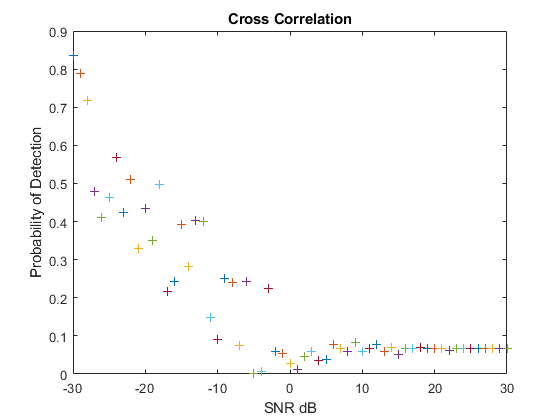

sinusPulse = Am*sin(2*pi*f0*t);  % Signal with multiple frequencies
mySNR = -30:30;
find_PD_PFa_2C(sinusPulse,50,mySNR)

function find_PD_PFa_2C(yourSignal,threshold,snr)
    for i = 1:length(snr)
        noisySignal = awgn(yourSignal,snr(i));
        [acor, ~] = xcorr(noisySignal,yourSignal);
%         save frrr.mat lag acor
        highVal = abs(acor) > threshold;
        Pd = sum(highVal)/length(highVal);
        plot(snr(i),Pd,'+')
        hold on
        title('Cross Correlation')
        ylabel('Probability of Detection')
        xlabel('SNR dB')
    end
    hold off
end